Necessary built-in functions

1. cwtft, continuous wavelet transform using FFT

2. dbaux, Daubechies wavelet filter computation

3. gauswavf, Gaussian wavelet

4. hlwt

5. hlwt2, Haar Integer Wavelet decomposition

6. meyer, Meyer wavelet

7, wavedemo

**About Wavelet**

**Applications:**

    Wavelet analysis is often capable of revealing characteristics of a signal or image that other analysis techniques miss., like trends, breakdown points, discontinuities in higher derivatives, and self-similarity. 

    Furthermore, because wavelets provide a different view of data than those presented by FT, wavelet analysis can often significantly compress or denoise a signal without appreciable degreation.

1. **Interactive tool ·wavemenu· **

**2. CWT**

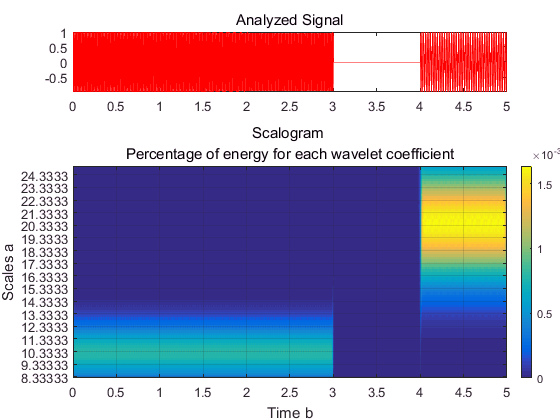

Fs = 1000;
fc = centfrq('cmor1-1');
freqrange = [40 120]; % interesting frequency range.
scalerange = fc./(freqrange*(1/Fs));
t = linspace(0,5,5e3);
x = cos(2*pi*100*t).*(t<3) + 1*cos(2*pi*50*t).*(4<t) + 0*randn(size(t));
scales = scalerange(end):0.2:scalerange(1);
Coeffs = cwt(x, scales, 'cmor1-1');
SCImg = wscalogram('image', Coeffs, ...
                   'scales', scales, ...
                   'ydata', x, ...
                   'xdata', t);
grid on;

**Something wrong?**

    two different-frequency cos are the same amplitude, what has caused the color different in energy percentage. 

**CWT & ICWT**

    use the discrete-Fourier transform-based CWT and inverse CWT

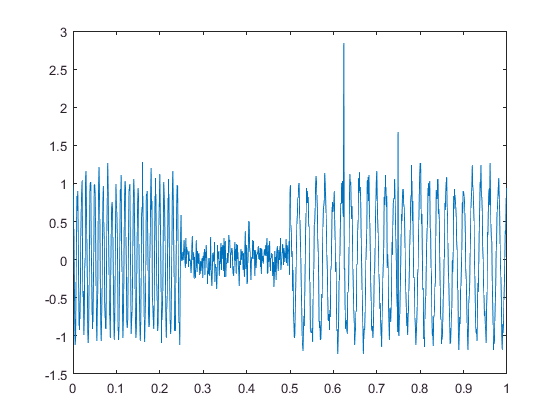

Fs = 1000;
t = 0:1/Fs:1-1/Fs;
x = zeros(size(t));
x([625,750]) = 2.5; % impules occur at 650-750ms
x = x + cos(2*pi*100*t).*(t<0.25)+cos(2*pi*50*t).*(t>=0.5) + 0.15*randn(size(t));
%   impulse    100Hz-cos         50Hz-cos                          random noise
figure;plot(t,x)

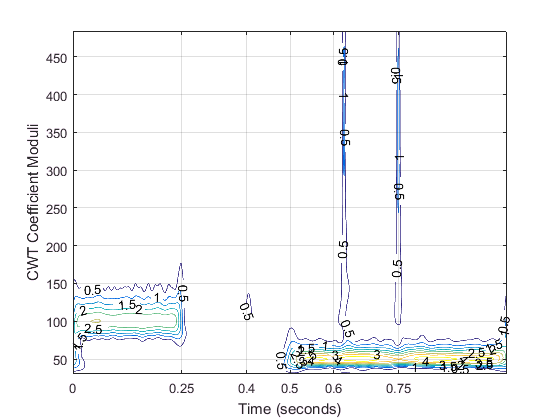

numvoices = 32;
numoctaves = 5;
a0 = 2^(1/numvoices); % a = 1.0219
scales = a0.^(numvoices:1/numvoices:numvoices*numoctaves).*1/Fs;

cwtstruct = cwtft({x, 1/Fs}, ...
                  'Scales', scales, ...
                  'Wavelet', 'morl');
              % Continous wavelet transform using FFT algorithm
              %% --Input parameters
              % sig, a cell array
              %    sig{1}, equal to the signal.
              %    sig{2}, sampling interval
              % scales
              % Wavelet 'morl' == Morlet wavelet
              
              %% --Output parameters
              % cfs, CWT coefficient matrix
              % scales, vector of scales at which the CWT is computed.
periods = cwtstruct.scales.*(4*pi)/(6+sqrt(38));
freq = 1./periods;
cfs = cwtstruct.cfs;
contour(t, freq, abs(cfs), ...
        'ShowText', 'on');
    %t, 0:1/Fs:1-1/Fs, 1x1000;
    %freq, [500, 0], 1x4097
    %cfs, 4097x1000;
set(gca, 'xtick', [0 0.25 0.4 0.5 0.6 0.75 1]);grid on;
xlabel('Time (seconds)');
ylabel('CWT Coefficient Moduli');

**Explanation:**

1. find main frequencier area, 100Hz±50Hz, 50Hz±20Hz, mainly focus on 50Hz, and 100Hz

    which could be identified in the source time series.

2. why is there a wide band around 100Hz, or 50Hz? It is the computation energy leak.

3. explanation on these two peaks around 0.6s and 0.75?

    You must know that  the frequency transformation of  contains all frequencies.

**Inverse CWT of Sine Wave**

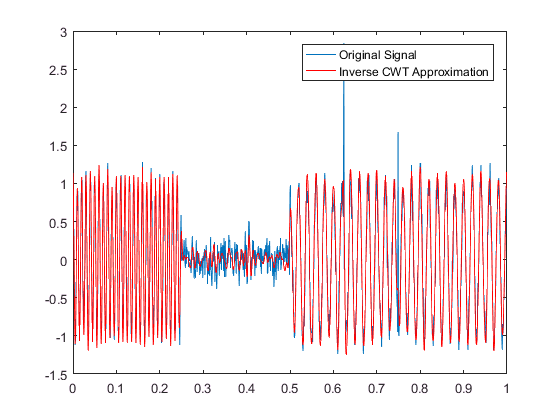

indices = find(scales>=0.007 & scales<=0.014 | scales>=0.015 & scales<=0.025);
% main frequencies,        100Hz,                          50Hz
icwtsin = cwtstruct;
icwtsin.cfs = zeros(size(cwtstruct.cfs));
icwtsin.cfs(indices, :) = cwtstruct.cfs(indices, :);
% only [main frequencies] parts are concerned. 

% x reconstruction
xrec = icwtft(icwtsin); 
close all;
plot(t, x);
hold on;
plot(t, xrec, 'r');
set(gca, 'xlim', [0 1]);
legend('Original Signal', 'Inverse CWT Approximation', ...
       'Location', 'NorthEast');

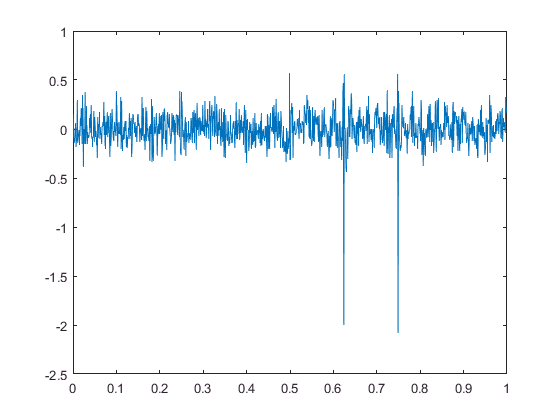

figure;
plot(t, xrec-x);

**Critically-Sampled Discrete Wavelet Analysis**

**1-D Wavelet Denoising**

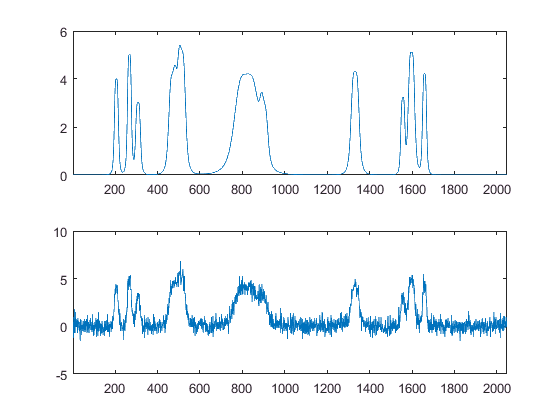

len = 2^11;
h = [4  -5  3  -4  5  -4.2   2.1   4.3  -3.1   5.1  -4.2];
t = [0.1  0.13  0.15  0.23  0.25  0.40  0.44  0.65  0.76  0.78  0.81];
h  = abs(h);
w = 0.01*[0.5 0.5 0.6 1 1 3 1 1 0.5 0.8 0.5];
tt = linspace(0,1,len);  
xref = zeros(1,len);
for j=1:11
    xref = xref + ( h(j)./(1 + ((tt-t(j))/w(j)).^4) );
end
rng default;
subplot(2,1,1);
plot(xref);
set(gca, 'xlim', [1 2048])

x = xref + 0.5*randn(size(xref));
subplot(2,1,2)
plot(x);
set(gca, 'xlim', [1 2048]);

Denoise the signal down to level 3 using the Daubechies least asymmetric wavelet with 4 vanishing moments.

Use the universal threshold selection rule of Donoho and Johnstone with soft thresholding based on the DWT

dwtmode('per');

 
!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
!  WARNING: Change DWT Extension Mode  !
!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


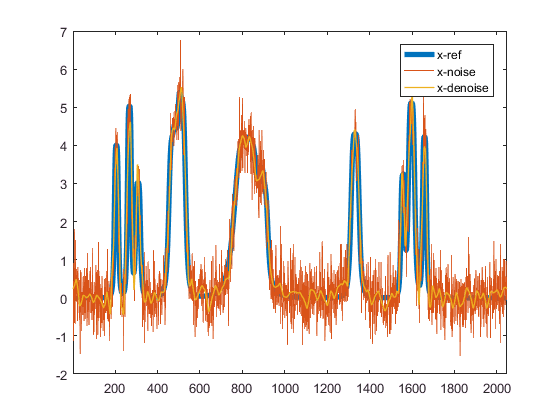

[xd, cxd, lxd] = wden(x, 'sqtwolog', 's', 'sln', 4, 'sym4');
                % automatic 1-D de-noising
figure;
plot([1:len], xref, 'LineWidth', 4);hold on;
plot([1:len], x, 'LineWidth',0.5);hold on;
plot([1:len], xd, 'LineWidth', 1);
set(gca, 'xlim', [1 2048]); 
legend('x-ref', 'x-noise', 'x-denoise');

**Lifting **

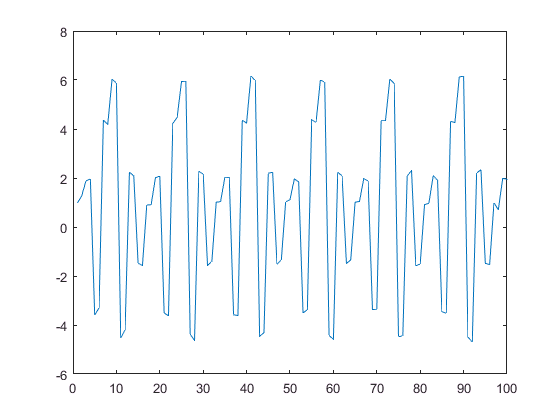

x = [1 1 2 2 -3.5 -3.5 4.3 4.3 6 6 -4.5 -4.5 2.2 2.2 -1.5 -1.5];
x = repmat(x, 1, 64);
% rng default;
x = x + 0.1*randn(size(x));
plot(x);set(gca, 'xlim', [0,100]);

Use the **Lazy **wavelet to obtain the even and odd polyphase components of the signal.

LS = liftwave('lazy');
[A, D] = lwt(x, LS); % 1-D lifting wavelet decomposition with respect to specified wavelet.

% add a dual lifting step
els = {'d', -1, 0};
LSnew = addlift(LS, els);
[Anew, Dnew] = lwt(x, LSnew);
% Results, average two neighbor points., to reduce aliasing.


**Nondecimated Discrete Wavelet Analysis -- Perfect decomposition results.**

    how to obtain the nondecimated (stationary) wavelet transform of a noise frequency-modulated signal.

    obtain more information on documentation of [**swc**]

    该函数的使用，恰好就是在《Wavelet Tutorial》教程中所说的subband coding，子带编码。

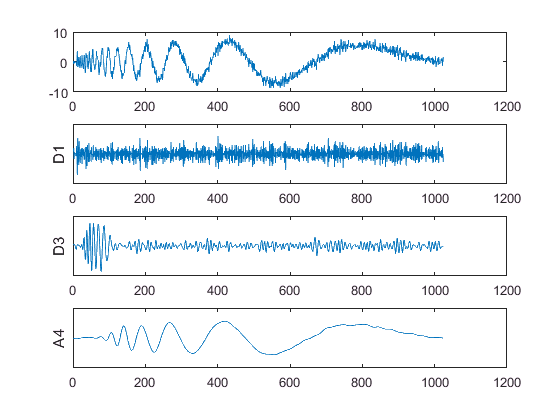

load noisdopp; % 1x1024
% stationary wavelet transformation 1-D
swc = swt(noisdopp, 4, 'sym8'); 
% 5x1024
subplot(411)
plot(noisdopp);
subplot(412);
plot(swc(1,:)); ylabel('D1');
set(gca,'ytick',[]);
subplot(413)
plot(swc(3,:)); ylabel('D3');
set(gca,'ytick',[]);
subplot(414);
plot(swc(5,:)); ylabel('A4');
set(gca,'ytick',[]);

**Critically Sampled Wavelet Packet Analysis**

    how to obtain the wavelet packet transform of  a 1-D signal

rng default;
dwtmode('per');

                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


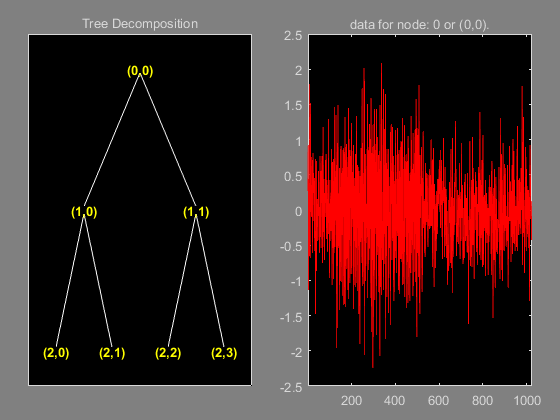

n = 0:1023;
indices = (n>127 & n<=512);
x = cos(7*pi/8*n).*indices + 0.5*randn(size(n));
T = wpdec(x, 2, 'sym4');
% Wavelet packet decomposiiton 1-D
plot(T); % nodes in the left plot is click-able.

[tn_pal, tn_freq] = otnodes(T);

**Summary: **除了能大概结合《Wavelet Tutorial》中的子带编码原理，其他不甚理解。

**Matching Pursuit  -- 完全不懂是是怎么回事**

    Matching Pursuit Dictionary Creation and VIsulization

[mpdict, ~, ~, longs] = wmpdictionary(100, 'lstcpt', {{'haar',2}});



**Time-Varying Coherence**

    how to use wavelet coherence to look for time-localized coherent oscillatory behavior in two time series.

    For nonstationary signals, a measure of  coherence that provides simultaneous time and frequency information is often more useful.

    function -- [**wcoherence**] -- wavelet coherence and cross-spectrum

**Remove Time-Localized Frequency Components**